# Ejemplo 1

## Preámbulo

close all;
clear all;

addPathToLibraries();

**************************
** myoClass toolbox     **
**************************



Loading global variables ...OK



## 1. Acediendo a la base de datos NINA

database_id = 1;
dataset_id = 1;
subject_id =1;
exercise_id = 1;

### 1.2 Lectura de la base de datos, dataset, sujeto y acción

% read a subject's data
s1 = loadSubjectData(database_id, dataset_id, subject_id, exercise_id);

### 1.3 Lectura de señal EMG

% read emg
emg_raw = getSEMG( s1 );

### 1.4 Visualización de las señales EMG

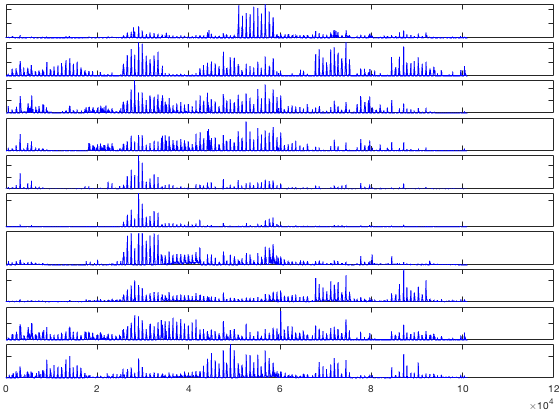

plotSEMGsignals( emg_raw );

## 2. Ejercicios: accesando el arreglo de muestras

### 2.1 Obtenga el número de muestras y número de señales

size(emg_raw)

ans =       101014          10


Número de muestras 101014

Número de señales o electrodos 10

### 2.2 Grafique las primeras 1000 muestras de la señal EMG número 3

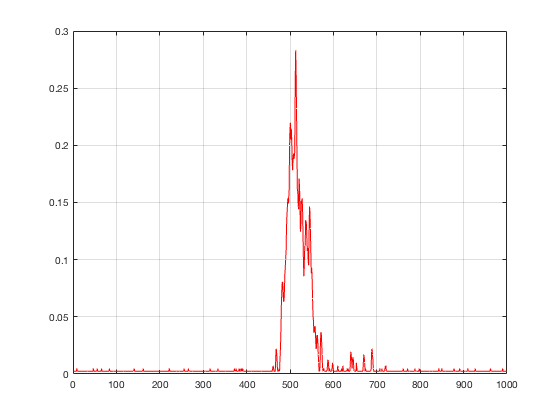

figure;
plot(emg_raw(1:1000,3),'-r');
grid on;

### 1.5 Grafique la muestra 1000 a 1800 de la señal EMG número 2

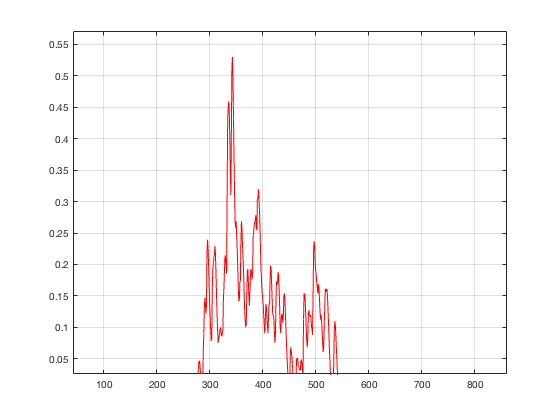

figure;
plot(emg_raw(1000:1800,2),'-r');
grid on;

## 3. Vector de estímulo

### 3.1 Lectura del vector de estímulo

% read stimulus vector
stimulus = getStimulus(s1);

### 3.1 Visualización del vector de estímulo

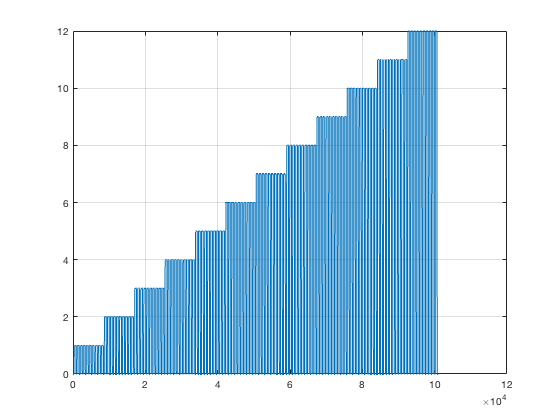

figure;
plot(stimulus);
grid on;

## 4. Ejercicios: accesando el vector de estímulos

##  4.1 Grafique el estímulo de la muestra 1000 a 1800

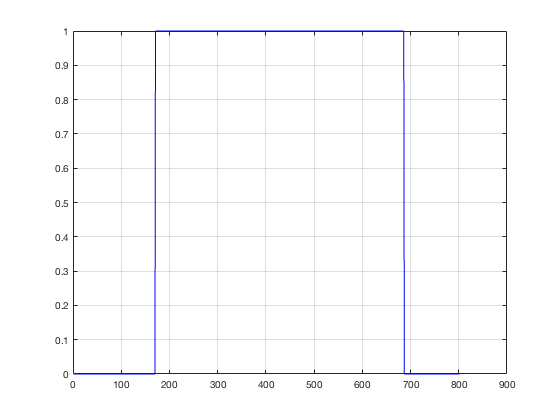

figure;
plot(stimulus(1000:1800),'-b');
grid on;

## 4.2 Grafique el estímulo de la muestra 90000 a 90800

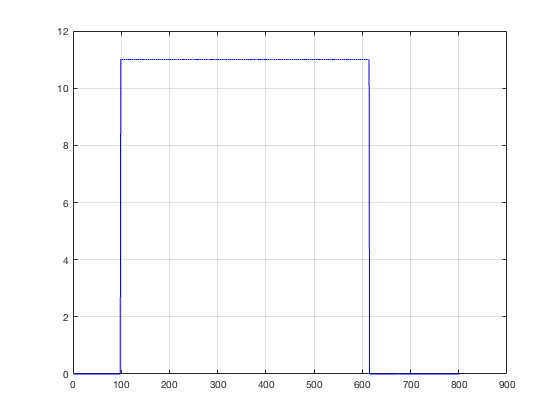

figure;
plot(stimulus(90000:90800),'-b');
grid on;

## 3. Vector de repetición

### 3.1 Lectura del vector de repetición

% read repetition vector
repetition = getRepetition(s1,2);

### 3.1 Visualización del vector de repetición

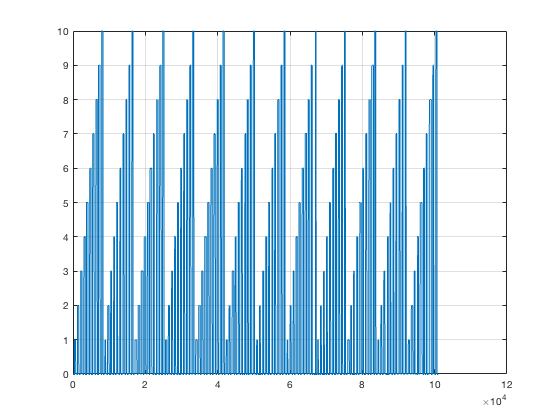

figure;
plot(repetition);
grid on;

## 5. Ejercicios: accesando el vector de estímulos

##  5.1 Grafique la repetición de la muestra 1000 a 3800

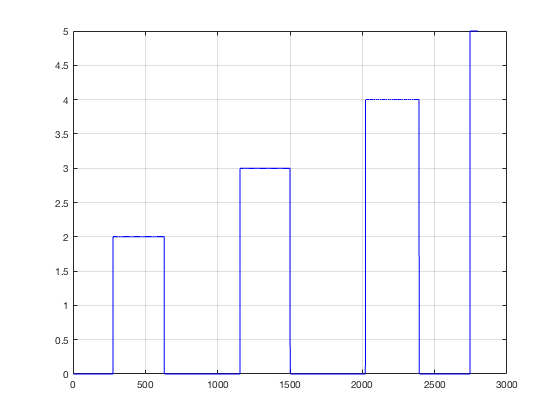

figure;
plot(repetition(1000:3800),'-b');
grid on;

## 5.2 Grafique la repetición de la muestra 90000 a 90800

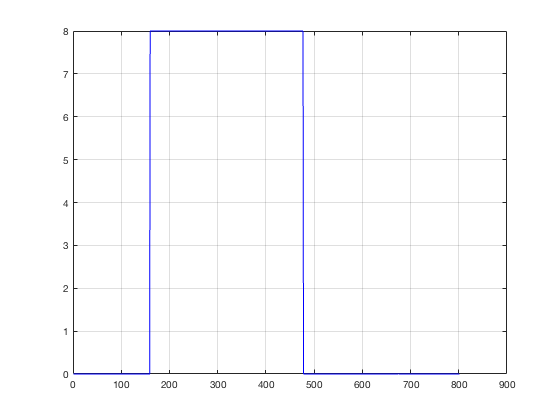

figure;
plot(repetition(90000:90800),'-b');
grid on;

## 6. Actividad

- Implemente una función que reduzca el offset de las señales EMG

- Implemente una función que filtre el ruido de las señales EMG (tecnica de filtro promedio)

- Implemente una función que filtre el ruido de las señales EMG (tecnica de transformada de Fourier, FFT)

- Códifique un live script que compare el resultado de los dos filtros sobre un mismo segmento de muestras EMG, asuma una frecuencia de muestro de $f_s = 100$ Hz